% Define file path (Update with your actual file location)
filePath ="C:\Users\dhiid\OneDrive\Desktop\Matlab simulations\tracking_data.csv";

% Read the CSV file into a table
data = readtable(filePath);

% Display first few rows to check structure
disp(data(1:5, :));

     Var1      Var2     Var3    Var4    Var5    Var6    Var7 
    _______    _____    ____    ____    ____    ____    _____

    0.18554    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.22273    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.24087    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.28597    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.33716    -7.24    9.38    -7.8    6.82    -100    -66.7




% Extract data (modify column indices if necessary)
x1 = data{:, 2}; % Current X values (actual system output)
y1 = data{:, 3};  
x2 = data{:, 4}; % Current X values (actual system output)
y2 = data{:, 5}; 

% Generate time (or sample index) for the system (assume unit time step)
numSamples = length(x1);
time = (1:numSamples)'; % Time vector

% Create input-output data for system identification (assumes x1 is output and x2 is input)
inputData = [y2]; % Setpoint is the input
outputData = [y1]; % System output is the observed x

% Open the PID Tuner GUI
% This will allow you to interactively tune the PID parameters.
% Once done, the `pidController` object will have the tuned PID controller.
% You can access the tuned PID gains as follows:
Kp = 18.6;
Ki = 7.9;
Kd = 0;

% Print out the tuned PID parameters
fprintf('Tuned PID Gains:\n');

Tuned PID Gains:


fprintf('Kp = %.4f\n', Kp);

Kp = 18.6000


fprintf('Ki = %.4f\n', Ki);

Ki = 7.9000


fprintf('Kd = %.4f\n', Kd);

Kd = 0.0000


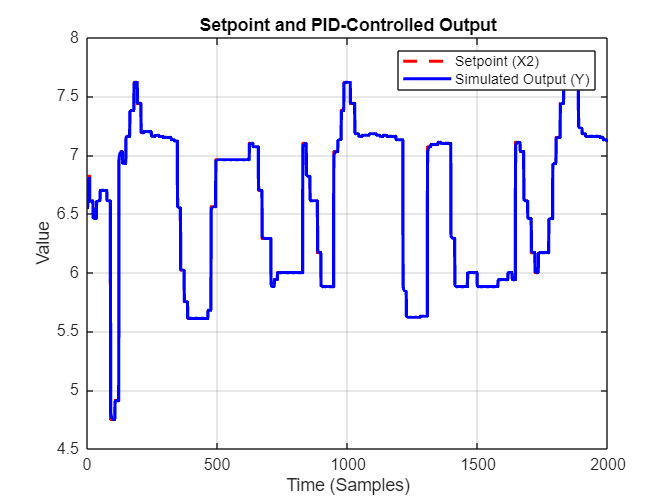


% Simulate the closed-loop system with the tuned PID controller
closedLoopSystem = feedback(pid(Kp, Ki, Kd) * sys, 1); % Unity feedback

% Simulate the system response over time
[y_sim, t_sim] = lsim(closedLoopSystem, inputData, time);

% Save the simulation results to a new CSV file
simResults = table(t_sim, y_sim);
writetable(simResults, 'tuned_pid_simulation_results.csv');

% Plot the results: compare the setpoint (x2) and the simulated output (y_sim)
figure;
plot(t_sim, inputData, '--r', 'LineWidth', 2, 'DisplayName', 'Setpoint (X2)');
hold on;
plot(t_sim, y_sim, '-b', 'LineWidth', 2, 'DisplayName', 'Simulated Output (Y)');
xlabel('Time (Samples)');
ylabel('Value');
title('Setpoint and PID-Controlled Output');
legend;
grid on;
hold off;


% Output the new PID parameters to a CSV file
pidResults = table(Kp, Ki, Kd);
writetable(pidResults, 'tuned_pid_parameters.csv');
